# Лабораторна робота No4

# Просторові перетворення зображень

clear; close all; clc;

## 1.  Завантаження зображень

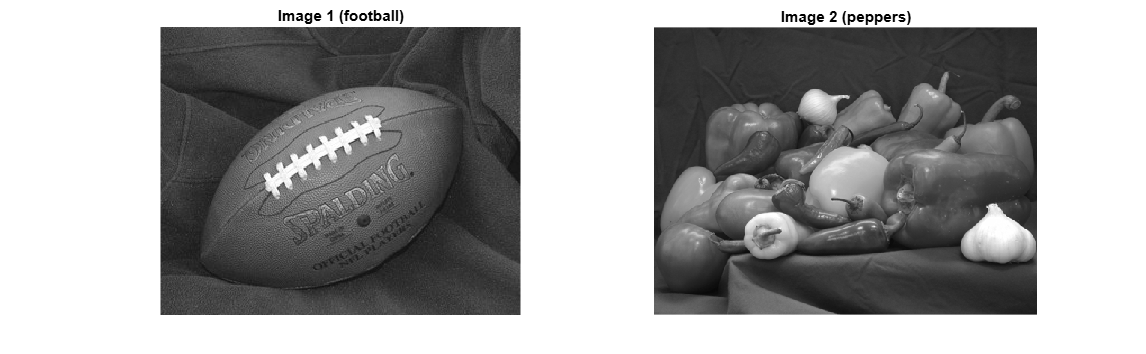

% завантаження фото з бібліотеки MATLAB
image1 = imread('football.jpg');
image2 = imread('peppers.png');

% перетворення з кольорових в чорно-біле зображення
image1 = rgb2gray(image1);
image2 = rgb2gray(image2);

% перетворення зображення або масиву в тип даних double з нормалізованими значеннями між 0 і 1
image1 = im2double(image1);
image2 = im2double(image2);

figure;
subplot(1,2,1), imshow(image1), title('Image 1 (football)');
subplot(1,2,2), imshow(image2), title('Image 2 (peppers)');
truesize;

## 2. Обчислення та відображення спектрів

Використовував тільки логарифмічний маштаб, без маштабування вручну.

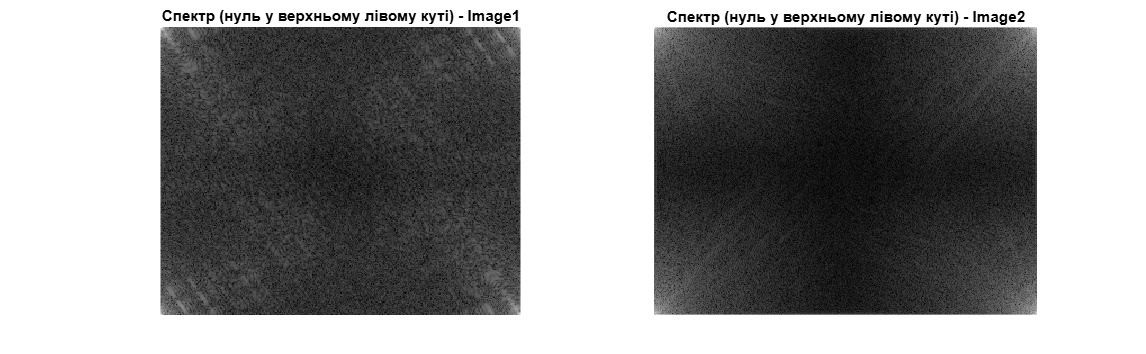

% двовимірне дискретне перетворення Фур’є (FFT – Fast Fourier Transform)
F1 = fft2(image1);
F2 = fft2(image2);

% Обчислюємо модуль комплексного спектра
S1 = abs(F1);
S2 = abs(F2);

% Логарифмічний маштаб
S1log = log(1 + S1);
S2log = log(1 + S2);

figure;
subplot(1,2,1), imshow(S1log, []), title('Спектр (нуль у верхньому лівому куті) - Image1');
subplot(1,2,2), imshow(S2log, []), title('Спектр (нуль у верхньому лівому куті) - Image2');
truesize;

## 3. Обчислення спектрів із застосуванням fftshift

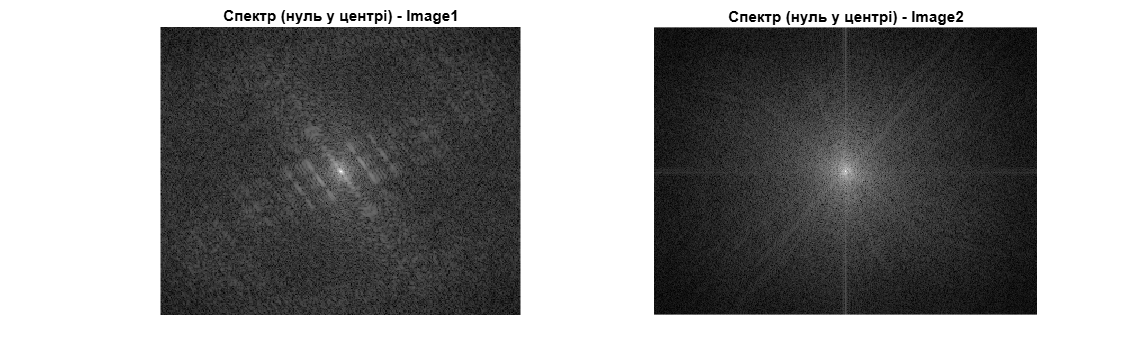

Fc1 = fftshift(S1);
Fc2 = fftshift(S2);

S1log_shift = log(1+Fc1);
S2log_shift = log(1+Fc2);

figure;
subplot(1,2,1), imshow(S1log_shift, []), title('Спектр (нуль у центрі) - Image1');
subplot(1,2,2), imshow(S2log_shift, []), title('Спектр (нуль у центрі) - Image2');
truesize;

## Невеликий тест на те чи впливає зміна послідовності на результат

Не впливає

test1 = log(1+abs(fftshift(F1)));
test2 = log(1+fftshift(S1));
test3 = fftshift(S1log);

figure;
subplot(1,2,1), imshow(log(1+abs(fftshift(F1))), []), title('Спектр (нуль у центрі) - Image1');
subplot(1,2,2), imshow(log(1+abs(fftshift(F2))), []), title('Спектр (нуль у центрі) - Image2');
truesize;

figure;
subplot(1,2,1), imshow(log(1+fftshift(S1)), []), title('Спектр (нуль у центрі) - Image1');
subplot(1,2,2), imshow(log(1+fftshift(S2)), []), title('Спектр (нуль у центрі) - Image2');
truesize;

figure;
subplot(1,2,1), imshow(fftshift(S1log), []), title('Спектр (нуль у центрі) - Image1');
subplot(1,2,2), imshow(fftshift(S2log), []), title('Спектр (нуль у центрі) - Image2');
truesize;

## 4. Відновлення зображень

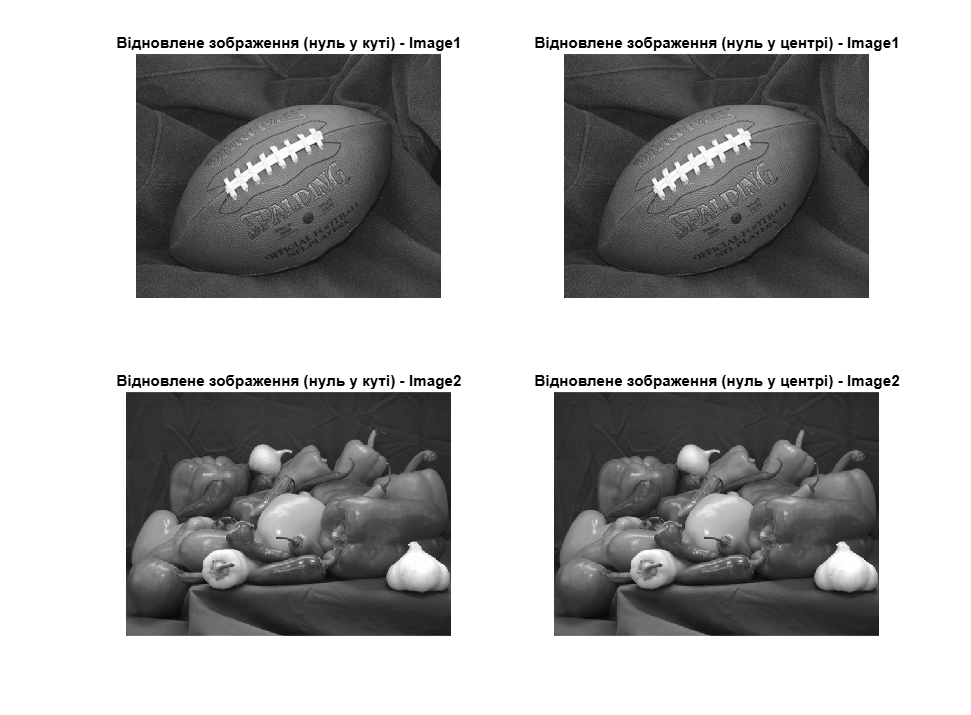

figure;
subplot(2,2,1), imshow(ifft2(F1)), title('Відновлене зображення (нуль у куті) - Image1');
subplot(2,2,2), imshow(ifft2(ifftshift(fftshift(F1)))), title('Відновлене зображення (нуль у центрі) - Image1');

subplot(2,2,3), imshow(ifft2(F2)), title('Відновлене зображення (нуль у куті) - Image2');
subplot(2,2,4), imshow(ifft2(ifftshift(fftshift(F2)))), title('Відновлене зображення (нуль у центрі) - Image2');
truesize;

## 5. Створення Гаусового фільтра

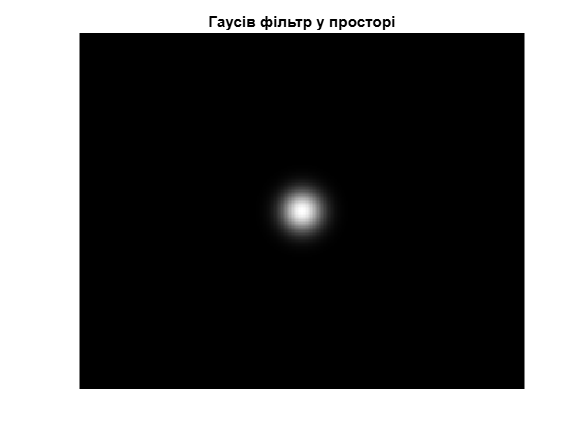

M = size(image1, 1);
N = size(image1, 2);
sigma = 10;

h = fspecial('gaussian', [M N], sigma);
figure, imshow(mat2gray(h)), title('Гаусів фільтр у просторі');

## 6. Частотна характеристика фільтра

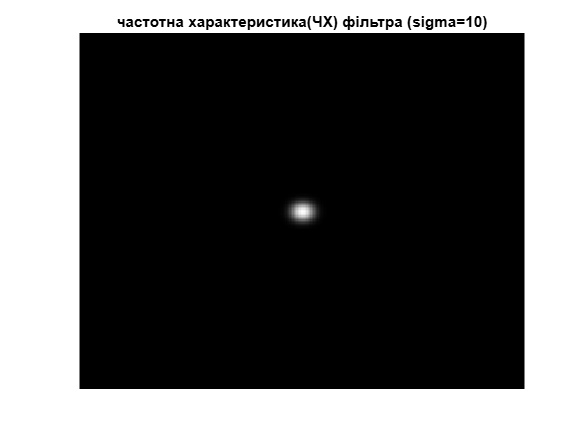

H = fft2(h);
H_shifted = fftshift(log(1 + abs(H)));

figure, imshow(mat2gray(H_shifted)), title('Частотна характеристика(ЧХ) фільтра (sigma=10)');

## 7. Зміна sigma та повторення пунктів 5-6

З малюнків видно, що чим менше розмір вікна фільтра, тим повільніше спадає частотна характеристика фільтра по мірі віддалення від центру, тобто тим більш це широкосмуговий фільтр. Якщо ж розмір вікна фільтра великий, то частотна характеристика убуває дуже швидко при віддаленні від центру вікна (від нуля). Тобто фільтр стає більш вузькополосним.

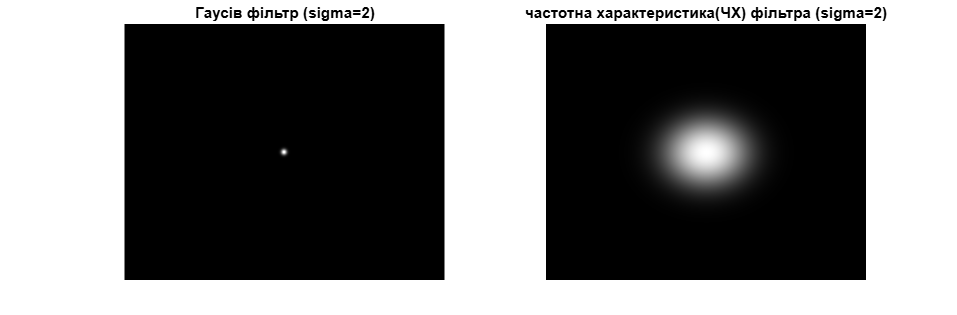

sigma2 = 2;
h2 = fspecial('gaussian', [M N], sigma2);
H2 = fft2(h2);
H2_shifted = fftshift(log(1 + abs(H2)));

figure;
subplot(1,2,1), imshow(mat2gray(h2)), title('Гаусів фільтр (sigma=2)');
subplot(1,2,2), imshow(mat2gray(H2_shifted), []), title('Частотна характеристика(ЧХ) фільтра (sigma=2)');
truesize;

## 8. Фільтрація зображень у частотній області з використанням фільтрів згідно п.п. 5, 6, 7.

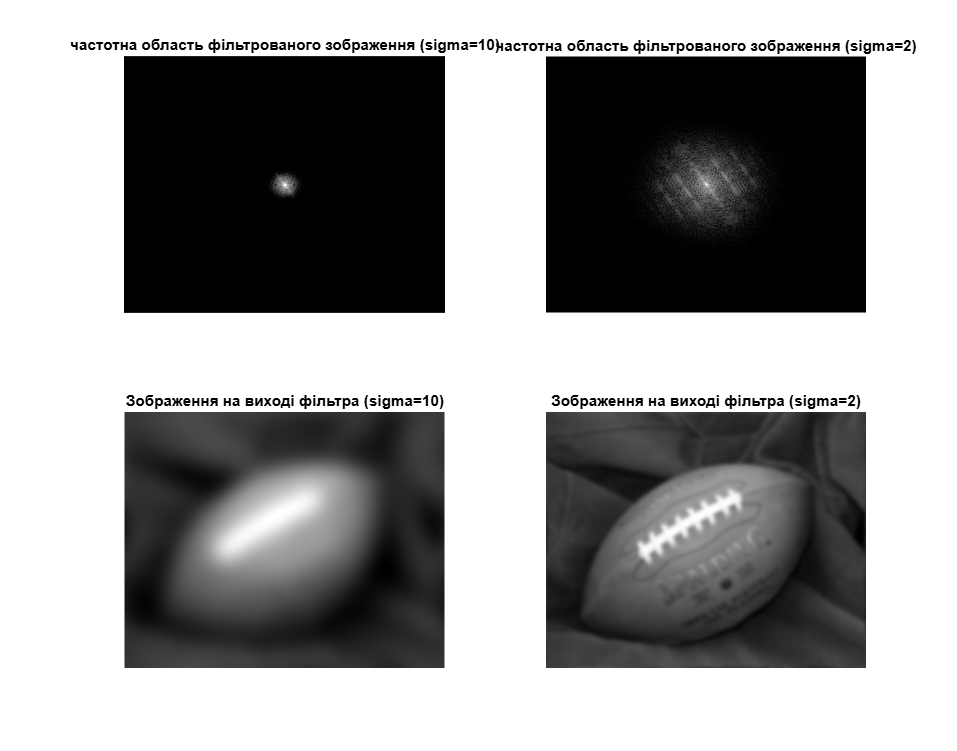

F1_filtered = F1 .* H;
F1_filtered2 = F1 .* H2;

Sifclog1 = log(1+fftshift(abs(F1_filtered)));
Sifclog2 = log(1+fftshift(abs(F1_filtered2)));

Filog1 = log(1+fftshift(abs(ifft2(F1_filtered))));
Filog2 = log(1+fftshift(abs(ifft2(F1_filtered2))));

figure;
subplot(2,2,1), imshow(Sifclog1, [ ]), title('частотна область фільтрованого зображення (sigma=10)');
subplot(2,2,2), imshow(Sifclog2, [ ]), title('частотна область фільтрованого зображення (sigma=2)');
subplot(2,2,3), imshow(Filog1, [ ]), title('Зображення на виході фільтра (sigma=10)');
subplot(2,2,4), imshow(Filog2, [ ]), title('Зображення на виході фільтра (sigma=2)');

## 9. Просторова фільтрація

**При порівнянні можна побачити що в п.8  отримане зображення більш контрастне ніж в п.9. Отримана різниця між частотною і просторовою фільтрацією це чисельні похибки, але результат за суттю той самий.**

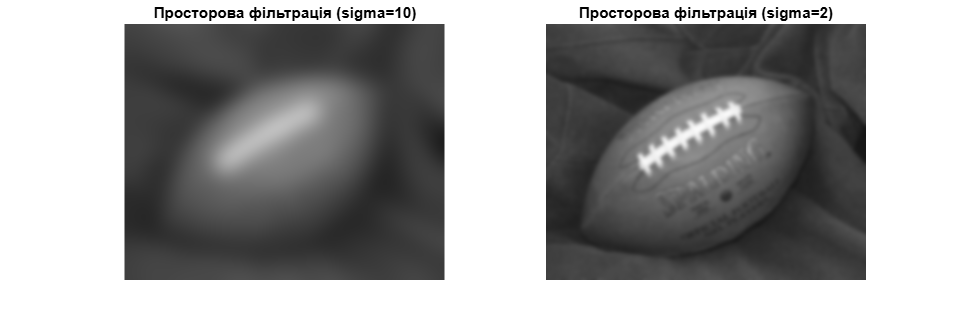

spatial_filtered1 = imfilter(image1, h, 'replicate');
spatial_filtered1_2 = imfilter(image1, h2, 'replicate');

figure;
subplot(1,2,1), imshow(spatial_filtered1), title('Просторова фільтрація (sigma=10)');
subplot(1,2,2), imshow(spatial_filtered1_2), title('Просторова фільтрація (sigma=2)');
truesize;